clc;
clear all;
warning off;
%% ==================== 1. 参数设置 ============================
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb_lag = [
      0       %S1
      0       %S2
      0       %S3
      0       %S4
     ]; 

ub_lag = [
      40       %S1
      40       %S2
      40       %S3
      40       %S4
     ];    

Npara_lag = length(lb_lag); 

S1 = 2;S2 = 5;
S3 = 2;S4 = 5;

para_init_lag = [S1,S2,S3,S4];

lb_cl = [
      0       %A1
      0       %b1
      0       %A2
      0       %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub_cl = [
      0.8     %A1
      0.8     %b1
      0.8     %A2
      0.8     %b2
      10      %Tp
      5       %Tf0
      15      %Tvl
      5      %Tv0
      0.95    %yita
     ];    

Npara_cl = length(lb_cl); 

A1   = 0.3         ; A2   = 0.3        ;
b1   = 0.3        ; b2   = 0.3           ;
Tp   = 5           ; Tf0  = 1             ;
Tvl  = 8            ; Tv0  = 2             ;
st   = 0.19          ; yita = 0.95          ;

para_init_cl = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

lb_cm = [
      0       %A3
      0       %b3
      0       %A4
      0       %b4
      0       %A5
      0       %b5
      0       %k0
      0       %k1
      0       %k2
      0       %k3
      0       %XCP
     ]; 

ub_cm = [
      0.5     %A3
      0.5     %b3
      0.5     %A4
      0.5     %b4
      0.5     %A5
      0.5     %b5
      0.5     %k0
      0.5     %k1
      0.5     %k2
      0.5     %k3
      0.5     %XCP
     ];    

Npara_cm = length(lb_cm); 

A3   = 0.2           ; b3   = 0.2           ;
A4   = 0.1           ; b4   = 0.1           ;
A5   = 0.1           ; b5   = 0.3           ;
k0   = 1             ; k1   = 1             ; 
k2   = 1             ; k3   = 1             ;
xcp = 0.2;

para_init_cm = [A3,b4,A4,b4,...
            A5,b5,k0,k1,...
            k2,k3,xcp];

para_init = [para_init_lag para_init_cl para_init_cm];

%% ==================== 2. 工况设置 ============================
meanangle    = 20;
averageangle = 10;
CFDdatapath = 'FFA_W3_211_rlt_20.txt';

conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

%% ==================== 3. 优化设置 ============================
para_local_lag = run_optimal_1lag(para_init_lag,para_init_cl,para_init_cm,Npara_lag,lb_lag,ub_lag,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
4 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 16 个工作进程的并行池。

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2955       10.8127            0      0
    2           5654       10.8094            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 10.80936403 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=11.080607 | 优化适应度=10.809364
   S1 : 原始值=2.000000 | 优化值=12.450936
   S2 : 原始值=5.000000 | 优化值=5.787569
   S3 : 原始值=2.000000 | 优化值=30.542490
   S4 : 原始值=5.000000 | 优化值=21.948567

优化结果已保存至：Boundary_layer_fitness.mat
历时 57.664960 秒。


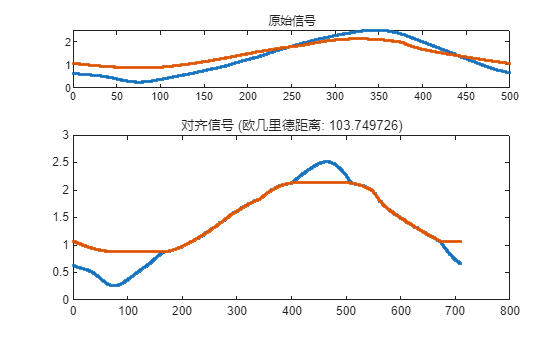

ans = 103.7497

ans = 103.7497

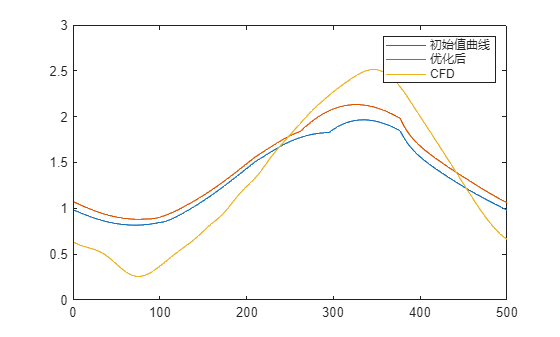

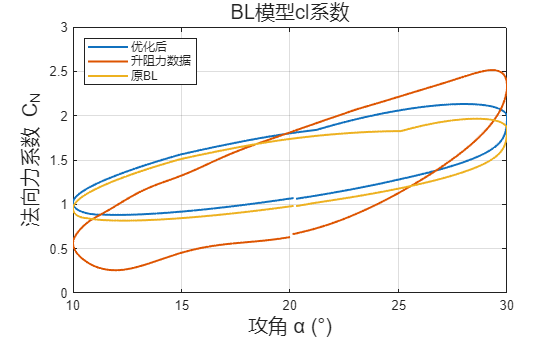


para_init_1 = [para_local_lag para_init_cl para_init_cm];

compare_optimal_result_lag(para_init_lag, para_init_cl, para_init_cm, para_local_lag, setcase);

para_local_cl = run_optimal_2cl(para_local_lag,para_init_cl,para_init_cm,Npara_cl,lb_cl,ub_cl,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2955       4.39452            0      0
    2           5654       4.31529            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 4.31528571 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=10.809364 | 优化适应度=4.315286
   A1 : 原始值=0.300000 | 优化值=0.149226
   b1 : 原始值=0.300000 | 优化值=0.607036
   A2 : 原始值=0.300000 | 优化值=0.413236
   b2 : 原始值=0.300000 | 优化值=0.726191
   Tp : 原始值=5.000000 | 优化值=2.546580
  Tf0 : 原始值=1.000000 | 优化值=4.521361
  Tvl : 原始值=8.000000 | 优化值=3.146533
  Tv0 : 原始值=2.000000 | 优化值=4.948731
 yita : 原始值=0.950000 | 优化值=0.85295

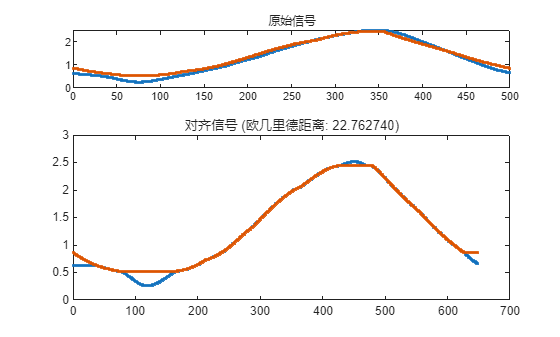

ans = 22.7627

ans = 22.7627

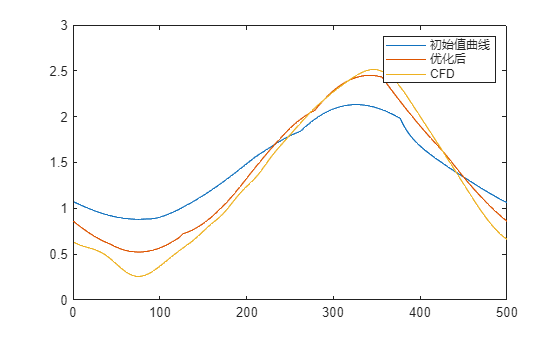

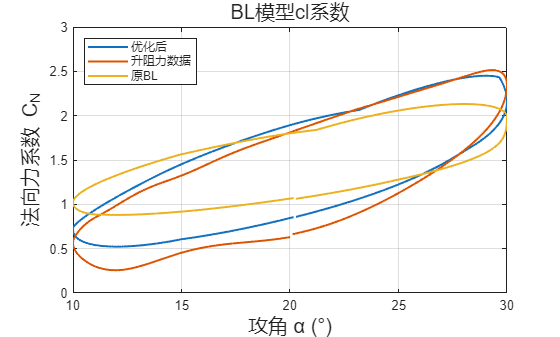


para_init_2 = [para_local_lag para_local_cl para_init_cm];

compare_optimal_result_cl(para_local_lag, para_init_cl, para_init_cm, para_local_cl,setcase);

para_local_cm = run_optimal_3cm(para_local_lag,para_local_cl,para_init_cm,Npara_cm,lb_cm,ub_cm,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
11 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2981        12.733       0.4775      0
优化结束: 找不到可行点。
===== 优化完成！最优适应度值 = 12.73300738 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=3.837766 | 优化适应度=12.733007
   A3 : 原始值=0.200000 | 优化值=0.200000
   b3 : 原始值=0.100000 | 优化值=0.100000
   A4 : 原始值=0.100000 | 优化值=0.100000
   b4 : 原始值=0.100000 | 优化值=0.100000
   A5 : 原始值=0.100000 | 优化值=0.100000
   b5 : 原始值=0.300000 | 优化值=0.300000
   k0 : 原始值=1.000000 | 优化值=0.500000
   k1 : 原始值=1.000000 | 优化值=0.500000
   k2 : 原始值=1.000000 | 优化值=0.500000
   k3 : 原始值=1.000000 | 优化值=0.500000
  xcp : 原始值=0.200000 | 优化值=0.200000

优化结果已保存至：parameters_cm.mat
历时 9.595839 秒。


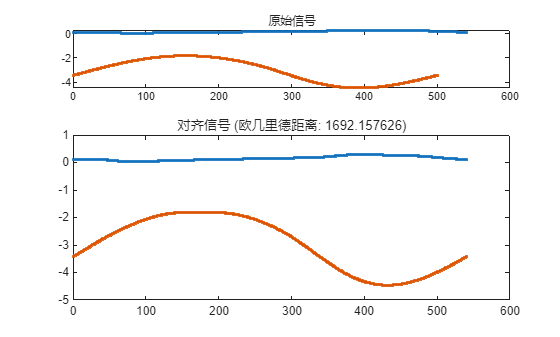

ans = 1.6922e+03

ans = 1.6922e+03

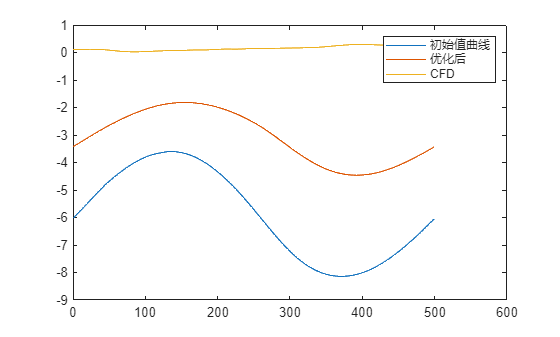

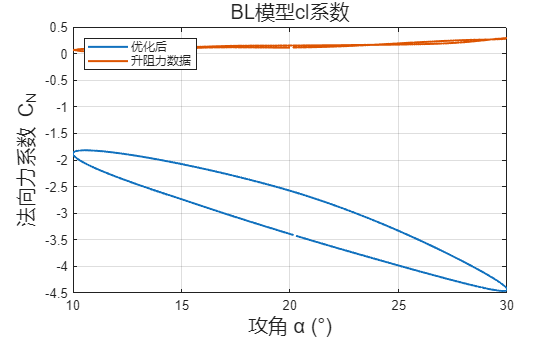


para_init_3 = [para_local_lag para_local_cl para_local_cm];

compare_optimal_result_cm(para_local_lag, para_local_cl, para_init_cm, para_local_cm, setcase);